rs =    625   750


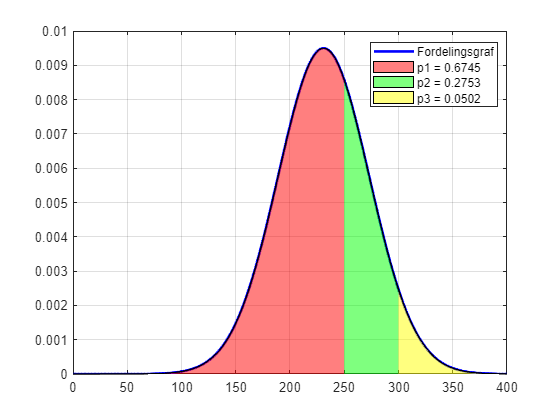

      Interval       Sandsynligheder    I procent
    _____________    _______________    _________

    "-inf -> 250"        0.6745         "67.45%" 
    "250 til 300"        0.2753         "27.53%" 
    "300 -> inf"         0.0502         " 5.02%" 
    "Sum"                     1         "  100%" 



clc;
clear all;

mu = 231;
sigma = 42;

inter = [250, 300];
iinter = [-100, 150, 200];

IntervalNormal(mu, sigma, 0, 400,inter)

rs =    250   375   500


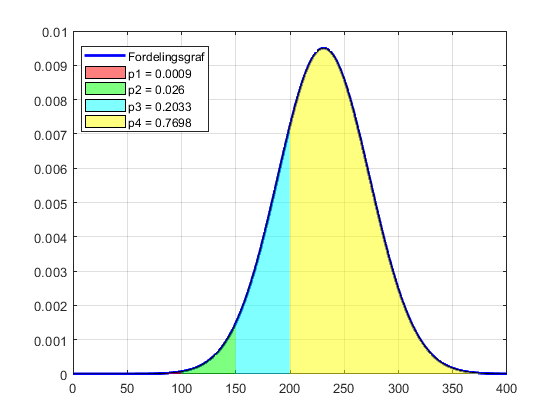

      Interval       Sandsynligheder    I procent
    _____________    _______________    _________

    "-inf -> 100"        0.0009         " 0.09%" 
    "100 til 150"         0.026         "  2.6%" 
    "150 til 200"        0.2033         "20.33%" 
    "200 -> inf"         0.7698         "76.98%" 
    "Sum"                     1         "  100%" 



IntervalNormal(mu, sigma, 0, 400,iinter)

rs =    300   400   500   600   700


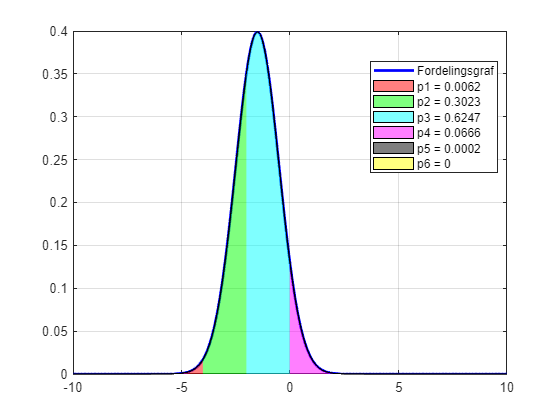

      Interval      Sandsynligheder    I procent
    ____________    _______________    _________

    "-inf -> -4"        0.0062         " 0.62%" 
    "-4 til -2"         0.3023         "30.23%" 
    "-2 til 0"          0.6247         "62.47%" 
    "0 til 2"           0.0666         " 6.66%" 
    "2 til 4"           0.0002         " 0.02%" 
    "4 -> inf"               0         "    0%" 
    "Sum"                    1         "  100%" 



clc;
clear all;

mu = -1.5;
sigma = 1;

inter = [-4, -2, 0, 2, 4];

IntervalNormal(mu, sigma, -10, 10,inter)

function Output = IntsdervalNormal(mu, sigma, mini, maxi, intervaller)

% Funktion til fill i arealer under plots
% Inputs er plottet, dets interval x, funktionsværdierne f(x), liste med
% navne over invervallernes værdier, og selve værdierne
% Inputs:
% Fordelingstype: Normal
% Sigma: Varians
% mu: Middelværdi
% Min og max værdier
% Intervaller: [[fra, til], [fra, til], ...] dobbelt [] ikke nødvendigt

% Genererer punkter
x = linspace(mini, maxi, 1000);

% Laver fordelingen
dist = makedist("Normal","mu",mu,"sigma",sigma);

% Genererer fordelingsværdier
pd = pdf(dist,x);

it = intervaller;

% kumulerede sandsynligheder
p_kum = [];
for i = 1:length(intervaller)
    p_kum(end+1) = normcdf(it(i), mu, sigma);
end

% Sandsynlighedsintervaller
p_int = [p_kum(1), ];
for j = 2:length(p_kum)
    p_int(end+1) = p_kum(j) - p_kum(j-1);
end


% Interval sandsynligheds array
p_int_f = [p_int, 1-p_kum(end)];
p_kum_f = [p_kum, 1-p_kum(end)];

% Displaynames
for l = 1:length(p_int_f)
    names(l) = "p"+l +" = " + round(p_int_f(l),4);
end


figure;
plot(x, pd, 'LineWidth',2, "DisplayName","Fordelingsgraf", Color="b"), xlim([mini, maxi]), grid();
hold on


% ranges
rs = [];
for d = 1:length(it)
    rs(end+1) = length(find(x<it(d)));
end
rs
% Første areal
area(x(1, 1:rs(1)), pd(1, 1:rs(1)), "DisplayName", names(1), facecolor="r");

%Plot colors
colors = ["g","c","m","k","w"];


for k = 2:length(rs)

    area(x(1, rs(k-1):rs(k)), pd(1, rs(k-1):rs(k)), "DisplayName",names(k), facecolor=colors(k-1));
    
end

% Sidste areal
area(x(1, rs(end):end), pd(1, rs(end):end), "DisplayName", names(end), facecolor="y");
alpha(0.5);
legend('show','location','best')
hold off

% Table over værdier


% Name generator
for g = 1:length(it)-1
    internames(g) = it(g) + " til " + it(g+1);
end

varnames = ["Interval", "Sandsynligheder", "I procent"];

internames = ["-inf -> " + num2str(it(1)),internames, num2str(it(end)) + " -> inf", "Sum"]';

intervals = round([p_int_f, sum(p_int_f)],4)';

intervals_procent = num2str(intervals*100) + "%";

disp(table(internames, intervals, intervals_procent, VariableNames=varnames))


end